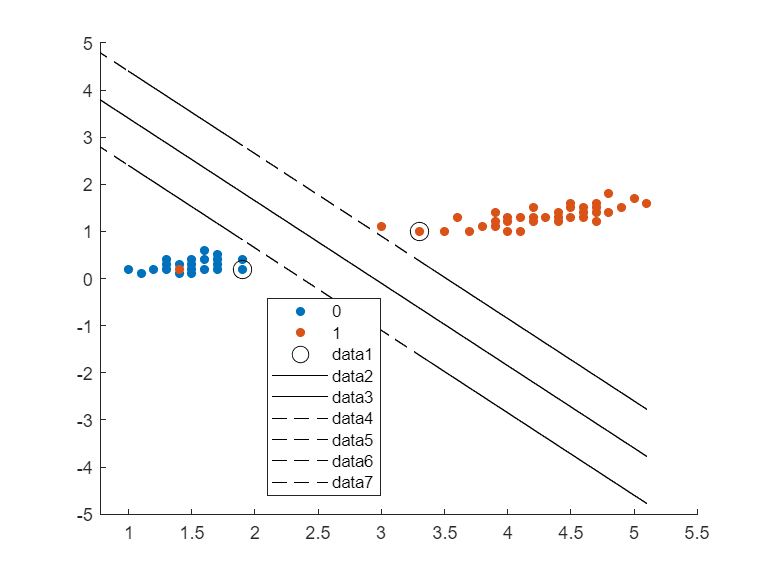

load fisheriris.mat;  %加载matlab自带鸢尾花数据集
X = meas(1:100, 3:4);  %取地3，4列
y = zeros(100,1);
y(50:100) = 1;
X_train = X([1:40, 51:90], :);  %选择其中80%的数据来训练，另外20%来测试
y_train = y([1:40, 51:90], :);
X_test = X([41:50, 91:100], :);
y_test = y([41:50, 91:100], :);

%新版matlab已经删除svmtrain函数，用fitsvm代替生成模型
svmmodel = fitcsvm(X_train,y_train);

%绘制点图
sv = svmmodel.SupportVectors;
hold on
gscatter(X(:,1),X(:,2),y)
plot(sv(:,1),sv(:,2),'ko','MarkerSize',10)

%绘制直线
a = - svmmodel.Beta(1)/svmmodel.Beta(2);
b = - svmmodel.Bias/svmmodel.Beta(2);
Y = a.*X_train + b;
Y2 = Y - 1;
Y3 = Y + 1;
plot(X_train,Y,'k-',X_train,Y2,'k--',X_train,Y3,'k--')


%输出测试准确度
y_predict = predict(svmmodel,X_test);
acc = sum(y_predict == y_test)/length(y_test)*100;
fprintf('%d\n', acc)

95
